syms s
A=[0 1 0;1 0 1;0 3 1];
B=[1;0;1];
x0=[1;1;1];
Uc=ctrb(A,B)

Uc =      1     0     2
     0     2     1
     1     1     7


syms f1 f2 f3 real
F=[f1 f2 f3]

$$F = \left(\begin{array}{ccc} f_{1} & f_{2} & f_{3} \end{array}\right)$$

coeffs(det(s*eye(3)-(A-B*F)),s)

$$ans = \left(\begin{array}{cccc} 2\,f_{3}-f_{2}-2\,f_{1}+1 & 2\,f_{2}-f_{1}-4 & f_{1}+f_{3}-1 & 1 \end{array}\right)$$

coeffs(((s+0.5)^2)*(s+0.2),s)

$$ans = \left(\begin{array}{cccc} \frac{1}{20} & \frac{9}{20} & \frac{6}{5} & 1 \end{array}\right)$$


pda=A^3+(6/5)*A^2+(9/20)*A+(1/20)*eye(3)

pda =     1.2500    4.4500    2.2000
    4.4500    7.8500    6.6500
    6.6000   19.9500   12.3000


F=[0 0 1]*inv(Uc)*pda

F =     0.6944    2.5722    1.5056


eig(A-B*F)

ans =   -0.5000 + 0.0000i
  -0.5000 - 0.0000i
  -0.2000 + 0.0000i




syms x1 x2 x3 real
solve(A*[x1;x2;x3]+B==0,[x1,x2,x3])

ans = フィールドをもつ struct :
    x1: -2
    x2: -1
    x3: 2


-inv(A)*B

ans =     -2
    -1
     2


xd=[-2;-1;2];
ud=1;
u=@(x) -F*(x-xd)+ud

u = 値をもつ function_handle :
    @(x)-F*(x-xd)+ud


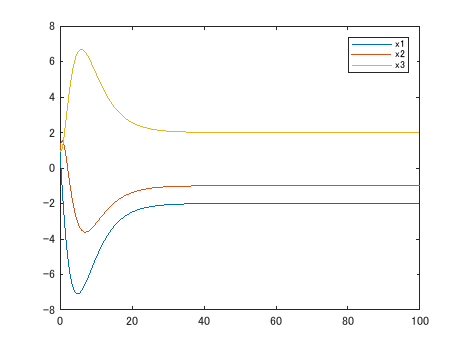

[T,X]=ode45(@(t,x)A*x+B*u(x),0:0.01:100,[1;1;1]);
plot(T,X)
legend('x1','x2','x3')


syms e1 e2 e3 real
e=x-xd;
[T,e]=ode45(@(t,e)x-xd,0:0.01:100,x0-xd);

次を使用中のエラー: odearguments
@(T,E)X-XD は列ベクトルを返さなければなりません。

エラー: ode45 (行 107)
    odearguments(odeIsFuncHandle,odeTreatAsMFile, solver_name, ode, tspan, y0, options, varargin);

plot(T,e)
legend('e1','e2','e3')